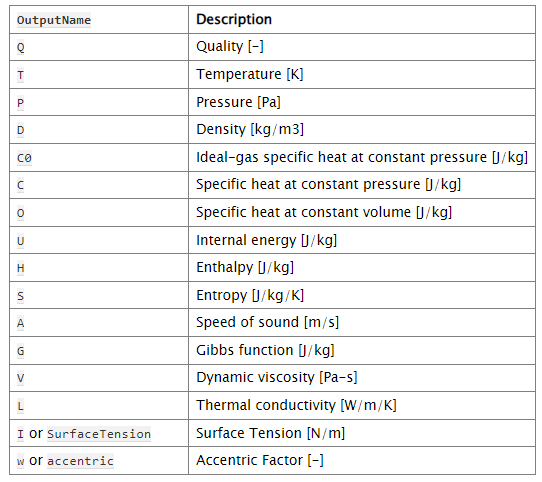

clear all
clf

% Importer CoolProp-modul 
% https://www.youtube.com/watch?v=XvR10Fjph7U&t=434s
% [v, e] = pyversion; system([e, ' -m pip install --user -U CoolProp'])
CoolProp = py.importlib.import_module('CoolProp.CoolProp');

% Stof (kan ændres efter behov)
fluid = 'Water';

% Temperatur og tryk (ændres efter behov)
T = 300; % Kelvin
P = 101325; % Pascal eller 1e5

% Beregn termodynamiske egenskaber
density = CoolProp.PropsSI('D', 'P', P, 'T', T, fluid);
enthalpy = CoolProp.PropsSI('H', 'P', P, 'T', T, fluid);
entropy = CoolProp.PropsSI('S', 'P', P, 'T', T, fluid);
specificHeat_p = CoolProp.PropsSI('Cpmass', 'P', P, 'T', T, fluid);
specificHeat_v = CoolProp.PropsSI('Cvmass', 'P', P, 'T', T, fluid);
thermalConductivity = CoolProp.PropsSI('conductivity', 'P', P, 'T', T, fluid);
eta = CoolProp.PropsSI('V', 'P', P, 'T', T, fluid);
specific_enthalpy = specificHeat_p * T

specific_enthalpy = 1.2542e+06

eta = nu * rho;

Unrecognized function or variable 'nu'.


% Vis resultater
disp('Density (kg/m^3): '), disp(density);
disp('Enthalpy (J/kg): '), disp(enthalpy);
disp('Entropy (J/kg.K): '), disp(entropy);
disp('Specific heat at constant pressure (J/kg.K): '), disp(specificHeat_p);
disp('Specific heat at constant volume (J/kg.K): '), disp(specificHeat_v);
disp('Thermal conductivity (W/m.K): '), disp(thermalConductivity);
disp('Viscosity (Pa.s): '), disp(viscosity);

## Fugtig luft

 pakken HumidAir package er inkluderede i coolpack

x_fugt = CP.HAPropsSI("W","R",phi,"T",273.15+T,"P",101325) % Fugtighedsratio kg/kg



## Energi lignigner

Her for kølekreds

syms q_mR h_1 h_2 h_3 h_4 Phi_komp Phi_K Phi_0 P_el
eq_energi_1 = q_mR * (h_1 - h_2) - Phi_komp + P_el == 0 % kompressor
latex(eq_energi_1)
eq_energi_2 = q_mR * (h_2 - h_3) - Phi_K == 0 % kodensator
eq_energi_3 = h_3 == h_4 % ekspandsions ventil
eq_energi_4 = q_mR * (h_4 - h_1) + Phi_0 == 0 % Fordamper
% latex(eq_energi_4)

## Tabel med nøgleværdier

**Område 1**

clear all
clf
% Importer CoolProp-modul
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
% Stof 
fluid = 'Air';

T_1 = 20 + 273.15;
P_1 = 1e5; %ps
h_1 = CoolProp.PropsSI('H', 'P', P_1, 'T', T_1, fluid);
rho_1 = CoolProp.PropsSI('D', 'P', P_1, 'T', T_1, fluid);
v_1 = 1/rho_1;
x_1 = CoolProp.PropsSI('Q', 'P', P_1, 'T', T_1, fluid);

**Område 2**

P_2 = 1e5 * 1.5; %ps
h_2 = vpasolve(eq_H_2, h_2)
T_2 = CoolProp.PropsSI('T', 'P', P_2, 'H', double(h_2), fluid);
rho_2 = CoolProp.PropsSI('D', 'P', P_2, 'T', T_2, fluid);
v_2 = 1/rho_2;
x_2 = CoolProp.PropsSI('Q', 'P', P_2, 'T', T_2, fluid);

**Område 3**

T_3 = 35 + 273.15;
P_3 = P_2;
h_3 = CoolProp.PropsSI('H', 'P', P_3, 'T', T_3, fluid);
rho_3 = CoolProp.PropsSI('D', 'P', P_3, 'T', T_3, fluid);
v_3 = 1/rho_3;
x_3 = CoolProp.PropsSI('Q', 'P', P_3, 'T', T_3, fluid);

**Område 4**

T_4 = 10 + 273.15;
P_4 = P_1;
h_4 = CoolProp.PropsSI('H', 'P', P_4, 'T', T_4, fluid);
rho_4 = CoolProp.PropsSI('D', 'P', P_4, 'T', T_4, fluid);
v_4 = 1/rho_4;
x_4 = CoolProp.PropsSI('Q', 'P', P_4, 'T', T_4, fluid);

**Table**

Temperatur_C = double([T_1, T_2, T_3, T_4]') - 273.15;
Tryk = double([P_1, P_2, P_3, P_4]') / 1e5;
Entalpi  = double([h_1, h_2, h_3, h_4]');
% Densitet = double([rho_1, rho_2, rho_3, rho_4]');
Specifik_vol = double([v_1, v_2, v_3, v_4]');
Kvalitet = double([x_1, x_2, x_3, x_4]');
T = table(Temperatur_C, Tryk, Entalpi, Specifik_vol, Kvalitet, ... %, Densitet
    VariableNames={'Temperatur (C)', 'Tryk (bar)', 'Spec entalpi h (J/kg)', 'Spec volumen (m^3/kg)', 'Kvalitet x'})


Logaritmisk middeltemperatur (LMTD) - modstrømsvarmeveksler

delta_t_max = T_2 - T_vand_max
delta_t_min = T_3 - T_vand_min
LMTD = (delta_t_max - delta_t_min) / log(delta_t_max / delta_t_min)

Find den isentrope eksponenten $\kappa$

c_p_luft = CoolProp.PropsSI('C', 'P', P_1, 'T', T_1, 'Air')
c_v_luft = CoolProp.PropsSI('O', 'P', P_1, 'T', T_1, 'Air')
kappa = c_p_luft/c_v_luft

## Fugtig luft

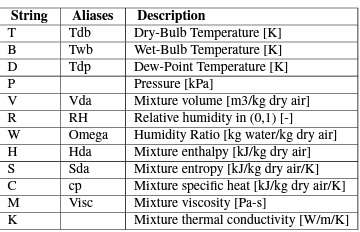

## T-s diagram

T_s = [linspace(T_1, T_2, 100); linspace(T_2, T_3, 100); linspace(T_3, T_4, 100); linspace(T_4, T_1, 100)];
size(T_s)
Entropy = zeros(4,100);
P_s = [P_1, P_2, P_3, P_4];
T_ss = [T_1, T_2, T_3, T_4, T_2, T_4-27];
for i = 1:length(P_s)
    for j = 1:100
        Entropy(i,j) = CoolProp.PropsSI('S', 'P', P_s(i), 'T', T_s(i,j), fluid);
    end
end

s_1 = CoolProp.PropsSI('S', 'P', P_1, 'T', T_1, fluid);
s_2 = CoolProp.PropsSI('S', 'P', P_2, 'T', T_2, fluid);
s_3 = CoolProp.PropsSI('S', 'P', P_3, 'T', T_3, fluid);
s_4 = CoolProp.PropsSI('S', 'P', P_4, 'T', T_4, fluid);
s_s = [s_1, s_2, s_3, s_4, s_1, s_3];

% plot(Entropy(1,:), T_s(1,:) - 273.15, '-', DisplayName='Kompressor')

plot(Entropy(2,:), T_s(2,:) - 273.15, '-', 'HandleVisibility','off')
hold on
plot([s_1, s_2], [T_1, T_2] - 273.15, '-', 'HandleVisibility','off')
plot([s_1, s_1], [T_1, T_2-2] - 273.15, '--', 'HandleVisibility','off')

plot([s_3, s_4], [T_3, T_4] - 273.15, '-', 'HandleVisibility','off')
plot([s_3, s_3], [T_3, T_4-27] - 273.15, '--', 'HandleVisibility','off')
plot(Entropy(4,:), T_s(4,:) - 273.15, '-', 'HandleVisibility','off')
% text(s_s(3), T_ss(3) - 273.15,  'hej')
scatter(s_s, T_ss - 273.15, 'HandleVisibility','off')

str_s = ['1', '2', '3', '4', "2s", "4s";]
for i = 1:length(T_ss)
    text(s_s(i) + 20, T_ss(i) - 273.15, str_s(i))
end

ylabel('Temperatur (C)')
xlabel('Entropi s (J/(kg K)')
grid('on')
% legend(Location="best")
hold off